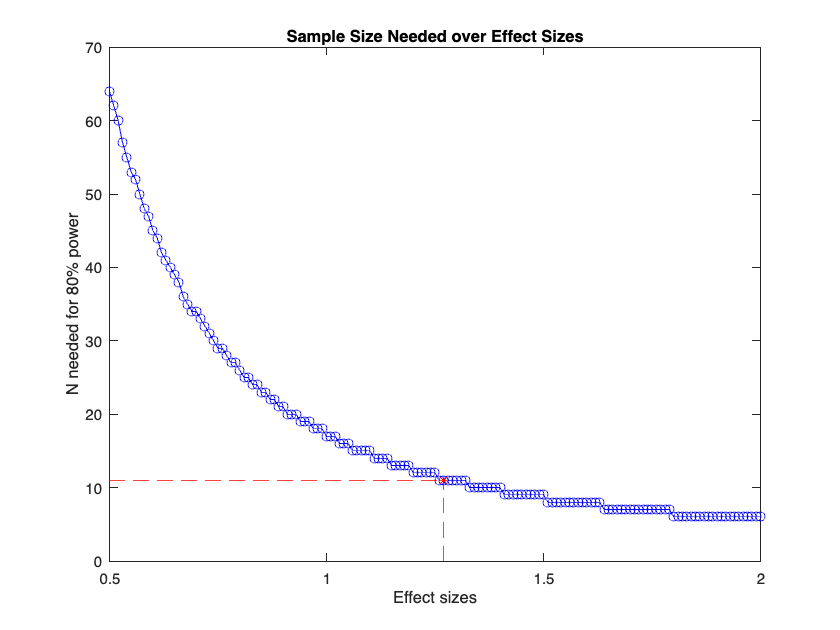

% We can perform a power analysis to find the n needed for different 
%  effect sizes at a given power (here 80%):
% A power analysis is by definition assuming there is an effect, so you
% give it the control and the experimental distribution assuming the
% experimental distribution has an effect. A standard assumption is that
% the stdv is 1 and the effect size is called in units of stdv (can be
% translated to measurements). How many n do i need if the effect size is x
% stdv away from the mean

% Argument 1: test type
test_type = 't2'; %I am assuming a t-distribution, essentially doing a two-sample t-test

% Argument 2: mean and std
P0 = [0 1];

% Argument 3: effect size
% Compute n at 80% power for different effect sizes (effect sizes are mean
% correlation coefficient for a positive effect)
effect_sizes = (0.5:0.01:2)';
num_effect_sizes = length(effect_sizes);

% Argument 4: power
power = 0.8;

% Loop through each effect size
ns = zeros(num_effect_sizes, 1);
for ii = 1:num_effect_sizes
   ns(ii) = sampsizepwr(test_type, P0, effect_sizes(ii), power);
end

plot(effect_sizes, ns, 'bo-')
hold on
y_val= sampsizepwr(test_type, P0, 1.27, power);
point=[1.27, y_val]; %This is the point on the graph for my estimated effect size 
plot(point(1), point(2), 'r*')
axLims = [0.5 2 0 70]; %set axis limits
xlim(axLims(1:2)); 
ylim(axLims(3:4)); 
hold on
plot([point(1), point(1)], [axLims(3), point(2)], 'r--')  %vertical line
plot([axLims(1), point(1)], [point(2), point(2)], 'r--')  %horizontal line
xlabel('Effect sizes');
ylabel('N needed for 80% power');
title('Sample Size Needed over Effect Sizes')



%effect size is the difference in means divided by the common standard
%deviation (average stdv). Plot both as a cumulative distribution to test if the
%distributions are different later on to test assumption of same
%distribution